# Compare backgroud rate by focal mechanism

load('mainshock_info.mat')

numMS = length(MSt);
timeWindow     = diff(minmax(MSt'));


## Fixed space window

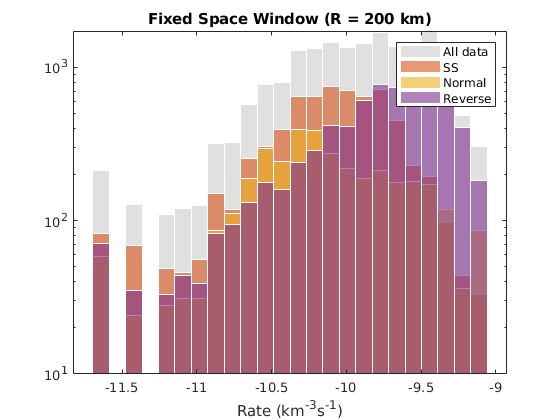

% compute background rate (BGR)
MSbgr = zeros(numMS,1);
spaceWindow = 200;
for n = 1:numMS   
    mapD    = distance(MSlat,MSlon,MSlat(n),MSlon(n));
    D       = sqrt(deg2km(mapD).^2 + (MSdepth-MSdepth(n)).^2);
    Iin     = D < spaceWindow;
    MSbgr(n)= log10(sum(Iin)./(timeWindow*4*pi*spaceWindow.^3/3)); 
end

figure 
resRange    = minmax(MSbgr');
binEdges    = linspace(resRange(1),resRange(2),25);
histogram(MSbgr,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
hold on
for iFMS = 1:3
    FMSloc  = MSfms == iFMS;
    histogram(MSbgr(FMSloc),binEdges,'EdgeColor',[1 1 1])
end

legend({'All data','SS','Normal','Reverse'})
titleStr = sprintf('Fixed Space Window (R = %g km)', spaceWindow);
title(titleStr)
xlabel('Rate (km^{-3}s^{-1})')
set(gca,'Yscale', 'log')

## Dynamic space window

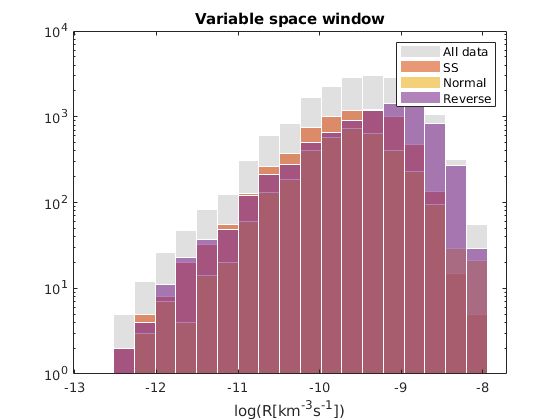

% compute background rate (BGR)
MSbgr = zeros(numMS,1);
for n = 1:numMS    
    mapD    = distance(MSlat,MSlon,MSlat(n),MSlon(n));
    D       = sqrt(deg2km(mapD).^2 + (MSdepth-MSdepth(n)).^2);    
    mo          = (10^((MSmag(n)+10.73)*1.5))*10^-7;
    stressDrop  = 10^5*10;
    sourceDim   = 2 * 0.001 * (mo*(7/16) / stressDrop) ^ (1/3); % in km tbl 9.1 modern global seismo lay
    spaceWindow  = 10*sourceDim; % 4 as per default setting in 
    Iin     = D < spaceWindow;
    MSbgr(n)= sum(Iin)./(timeWindow*4*pi*spaceWindow.^3/3); 
end

figure 
resRange    = minmax(log10(MSbgr'));
binEdges    = linspace(resRange(1),resRange(2),20);
histogram(log10(MSbgr),binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
hold on
for iFMS = 1:3
    FMSloc  = MSfms == iFMS;
    histogram(log10(MSbgr(FMSloc)),binEdges,'EdgeColor',[1 1 1])
end

legend({'All data','SS','Normal','Reverse'})
xlabel('log(R[km^{-3}s^{-1}])')
title('Variable space window')
set(gca,'YScale', 'log')

## Compare to residual productivity

figure

Undefined function or variable 'MS'.